# Kalman Consensus Filter

## Setup

del_t = 1; % time step
itr = 100; % total time steps
random_acc_sd = 0.2;

% Sensor noise
sens1_sd = 0.5; % 1.17
sens2_sd = 1.0; % 1.0
sens3_sd = 1.5; % 1.5
sens4_sd = 2.0; % 1.3
sensor_noise = [0,0,0,0;sens1_sd,sens2_sd,sens3_sd,sens4_sd];

N = 4; % # sensors
eps = 0.05; % Consensus term

% Initial guess
init_x = [0 0 0 0 0 0]';
init_p = [500 0 0 0 0 0;
          0 500 0 0 0 0;
          0 0 500 0 0 0;
          0 0 0 500 0 0;
          0 0 0 0 500 0;
          0 0 0 0 0 500];

% State transistion model
f = [1 del_t 0.5*power(del_t,2) 0 0 0;
     0 1 del_t 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 del_t 0.5*power(del_t,2);
     0 0 0 0 1 del_t;
     0 0 0 0 0 1];

% Process noise
q = [power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2 0 0 0;
     power(del_t,3)/2 power(del_t,2)/2 del_t 0 0 0;
     power(del_t,2)/2 del_t 1 0 0 0;
     0 0 0 power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2;
     0 0 0 power(del_t,3)/2 power(del_t,2)/2 del_t;
     0 0 0 power(del_t,2)/2 del_t 1];
q = q * power(random_acc_sd,2);

% Measurement model
h = [1 0 0 0 0 0; % TODO: Separate H for each sensors
     0 0 0 1 0 0];

% Mesurement noise
R = NaN(2,2,N);
R(:,:,1) = [power(sensor_noise(2,1),2) 0;
      0 power(sensor_noise(2,1),2)];
R(:,:,2) = [power(sensor_noise(2,2),2) 0;
      0 power(sensor_noise(2,2),2)];
R(:,:,3) = [power(sensor_noise(2,3),2) 0;
      0 power(sensor_noise(2,3),2)];
R(:,:,4) = [power(sensor_noise(2,4),2) 0;
      0 power(sensor_noise(2,4),2)];

## Generate sensor values

z0 = gen_sens_val(true_x,true_y,0.5); % TODO: needs to come from the benchmark from paper
z1 = gen_sens_val(true_x,true_y,sensor_noise(2,1));
z2 = gen_sens_val(true_x,true_y,sensor_noise(2,2));
z3 = gen_sens_val(true_x,true_y,sensor_noise(2,3));
z4 = gen_sens_val(true_x,true_y,sensor_noise(2,4));

Z = zeros(2,4,length(z1));
Z(:,1,:) = z1;
Z(:,2,:) = z2;
Z(:,3,:) = z3;
Z(:,4,:) = z4;

% draw_trajectory(z1(1,:),z1(2,:),'r');
% draw_trajectory(z2(1,:),z2(2,:),'g');
% draw_trajectory(z3(1,:),z3(2,:),'b');
% draw_trajectory(z4(1,:),z4(2,:),'m');

## Initialization

% Prediction Step
x_1 = f*init_x;
p_1 = f*init_p*f' + q;

% X_0 = [x_1 x_2 x_3 x_4];
% P_0 = zeros(6,6,N);
% P_0(:,:,1) = p_1;
% P_0(:,:,2) = p_2;
% P_0(:,:,3) = p_3;
% P_0(:,:,4) = p_4;

% Helper variables

% JR = ["r1","r2","r4";
%       "r2","r3","r1";
%       "r3","r4","r2";
%        "r4","r1","r3"];
% 
% JZ = ["z1","z2","z4";
%       "z2","z3","z1";
%       "z3","z4","z2";
%       "z4","z1","z3"];

J = [ 1 2 4; 2 3 1; 3 4 2; 4 1 3];

% Storage initialization
X_est = NaN(6,N,itr);
P_est = NaN(6,6,N,itr);
% x_est = NaN(6,length(z1));

X_pred = NaN(6,N,itr+1);
P_pred = NaN(6,6,N,itr+1);

X_pred(:,1,1) = x_1;
X_pred(:,2,1) = x_1;
X_pred(:,3,1) = x_1;
X_pred(:,4,1) = x_1;

P_pred(:,:,1,1) = p_1;
P_pred(:,:,2,1) = p_1;
P_pred(:,:,3,1) = p_1;
P_pred(:,:,4,1) = p_1;


## Algorithm

for i = 1:itr
    % At each iterations
    for n = 1:4
        % for every sensor
        msg.y_n = zeros(6,N-1); % measurement % N-1 because each sensor can have two neighboring sensor + itself
        msg.s_n = zeros(6,6,N-1); % covariance
        msg.x_n = zeros(2,N-1); % state estimate
        for nei = 1:N-1
            % for every neighbour
            j = J(n,nei);
            r_nei = R(:,:,j);
            % r_nei = eval(JR(n,nei));
            z_nei = Z(:,j,i);
            % z_nei = eval(JZ(n,nei));
            msg.y_i(:,nei) = h'*inv(r_nei)*z_nei;
            msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
            msg.x_i(:,nei) = z_nei;
        end

        % current state estimate
        y_i = zeros(6,1);
        s_i = zeros(6,6);
        x_diff_sum = 0;
        for m = 1:N-1
            y_i = y_i + msg.y_i(:,m);
            s_i = s_i + msg.s_i(:,:,m);
            if m ~= 1
                x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
            end
        end
        x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';

        M_i = inv(inv(P_pred(:,:,n,i)) + s_i);
        x_p = X_pred(:,n,i);
        innov = y_i - (s_i*x_p);
        x_est = x_p + (M_i*innov) + (eps*M_i*x_diff_sum);

        % Update state
        p_next = f*M_i*f' + q;
        x_next = f*x_est;

        % Store values
        X_est(:,n,i) = x_est;
        X_pred(:,n,i+1) = x_next;
        P_pred(:,:,n,i+1) = p_next;
    end

    % if i == 1
    %     % At each iterations
    %     for n = 1:4
    %         % for every sensor
    %         msg.y_i = zeros(6,N-1);
    %         msg.s_i = zeros(6,6,N-1);
    %         msg.x_i = zeros(2,N-1);
    %         for nei = 1:3
    %             % for every neighbour
    %             r_nei = eval(JR(n,nei));
    %             z_nei = eval(JZ(n,nei));
    %             msg.y_i(:,nei) = h'*inv(r_nei)*z_nei(:,i);
    %             msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
    %             msg.x_i(:,nei) = z_nei(:,i);
    %         end
    %         %Compute estimate
    %         y_i = zeros(6,1);
    %         s_i = zeros(6,6);
    %         x_diff_sum = 0;
    %         for m = 1:N-1
    %             y_i = y_i + msg.y_i(:,m);
    %             s_i = s_i + msg.s_i(:,:,m);
    %             if m ~= 1
    %                 x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
    %             end
    %         end
    %         x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
    %         M_i = inv(inv(P_0(:,:,n)) + s_i);
    %         x_p = X_0(:,n);
    %         innov = y_i - (s_i*x_p);
    %         x_est = x_p + (M_i*innov) + (eps*M_i*x_diff_sum);
    % 
    %         % Update state
    %         p_next = f*M_i*f' + q;
    %         x_next = f*x_est;
    % 
    %         % Store values
    %         X_est(:,i,n) = x_est;
    %         X_pred(:,:,i+1,n) = x_next;
    %         P_pred(:,:,i+1,n) = p_next;
    %         % disp(n);
    %         % disp(X_est);
    %         % disp("-------------------------");
    %     end
    % else
    %     % At each iterations
    %     for n = 1:4
    %         % for every sensor
    %         msg.y_i = zeros(6,N-1);
    %         msg.s_i = zeros(6,6,N-1);
    %         msg.x_i = zeros(2,N-1);
    %         for nei = 1:3
    %             % for every neighbour
    %             r_nei = eval(JR(n,nei));
    %             z_nei = eval(JZ(n,nei));
    %             msg.y_i(:,nei) = h'*inv(r_nei)*z_nei(:,i);
    %             msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
    %             msg.x_i(:,nei) = z_nei(:,i);
    %         end
    %         %Compute estimate
    %         y_i = zeros(6,1);
    %         s_i = zeros(6,6);
    %         x_diff_sum = 0;
    %         for m = 1:N-1
    %             y_i = y_i + msg.y_i(:,m);
    %             s_i = s_i + msg.s_i(:,:,m);
    %             if m ~= 1
    %                 x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
    %             end
    %         end
    %         x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
    %         M_i = inv(inv(P_pred(:,:,i)) + s_i);
    %         x_p = X_pred(:,:,i);
    %         innov = y_i - (s_i*x_p);
    %         x_est = x_p + M_i*innov + eps*M_i*x_diff_sum;
    % 
    %         % Update state
    %         p_next = f*M_i*f' + q;
    %         x_next = f*x_est;
    % 
    %         % Store values
    %         X_pred(:,:,i+1,n) = x_next;
    %         P_pred(:,:,i+1,n) = p_next;
    %         X_est(:,i,n) = x_est;
    %     end
    % end
end


## Visualization

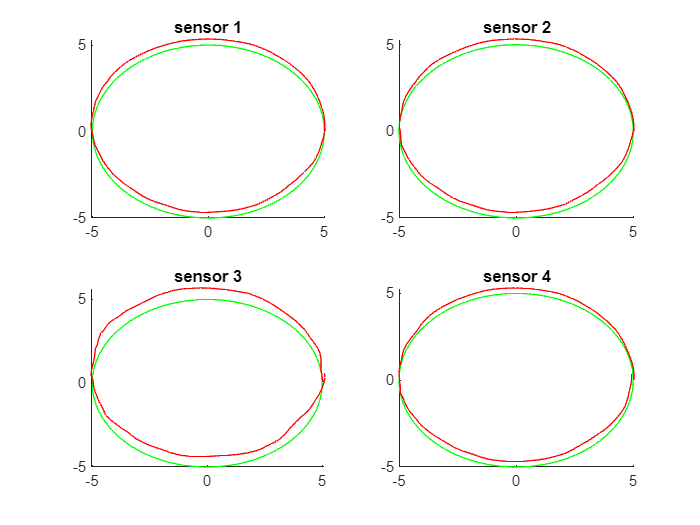

% figure;
[true_x,true_y] = gen_true_val(0,0,5);
% draw_trajectory(true_x,true_y,'k');
% hold on;

est_x_1 = X_est(1,1,:);
est_y_1 = X_est(4,1,:);
est_x_1 = reshape(est_x_1,[1,itr]);
est_y_1 = reshape(est_y_1,[1,itr]);
figure;
subplot(2,2,1);
hold on;
draw_trajectory(true_x,true_y,"g");
% draw_trajectory(z0(1,:),z0(2,:),'k');
draw_trajectory(est_x_1,est_y_1,"r");
title("sensor 1");

est_x_2 = X_est(1,2,:);
est_y_2 = X_est(4,2,:);
est_x_2 = reshape(est_x_2,[1,itr]);
est_y_2 = reshape(est_y_2,[1,itr]);
subplot(2,2,2);
hold on;
draw_trajectory(true_x,true_y,"g");
draw_trajectory(est_x_2,est_y_2,"r");
title("sensor 2");

est_x_3 = X_est(1,3,:);
est_y_3 = X_est(4,3,:);
est_x_3 = reshape(est_x_3,[1,itr]);
est_y_3 = reshape(est_y_3,[1,itr]);
subplot(2,2,3);
hold on;
draw_trajectory(true_x,true_y,"g");
draw_trajectory(est_x_3,est_y_3,"r");
title("sensor 3");

est_x_4 = X_est(1,4,:);
est_y_4 = X_est(4,4,:);
est_x_4 = reshape(est_x_4,[1,itr]);
est_y_4 = reshape(est_y_4,[1,itr]);
subplot(2,2,4);
hold on;
draw_trajectory(true_x,true_y,"g");
draw_trajectory(est_x_4,est_y_4,"r");
title("sensor 4");

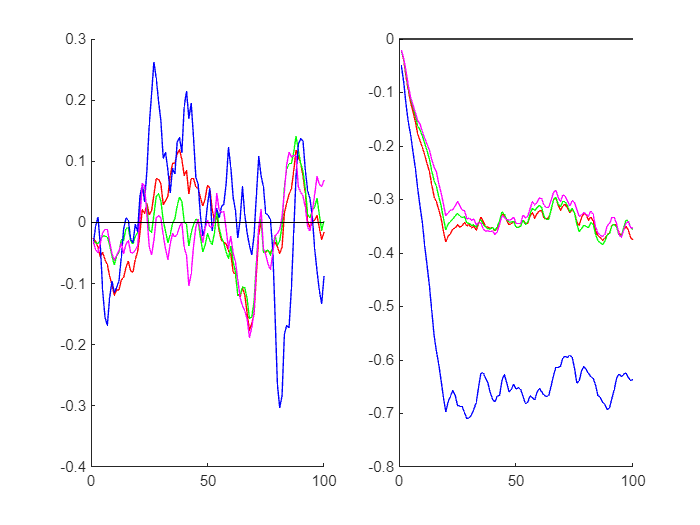

figure;
subplot(1,2,1);
hold on;
plot(true_x-est_x_1, 'r');
plot(true_x-est_x_2, 'g');
plot(true_x-est_x_3, 'b');
plot(true_x-est_x_4, 'm');
plot([0 100],[0 0],'k');
subplot(1,2,2);
hold on;
plot(true_y-est_y_1,'r');
plot(true_y-est_y_2,'g');
plot(true_y-est_y_3,'b');
plot(true_y-est_y_4,'m');
plot([0 100],[0 0],'k');

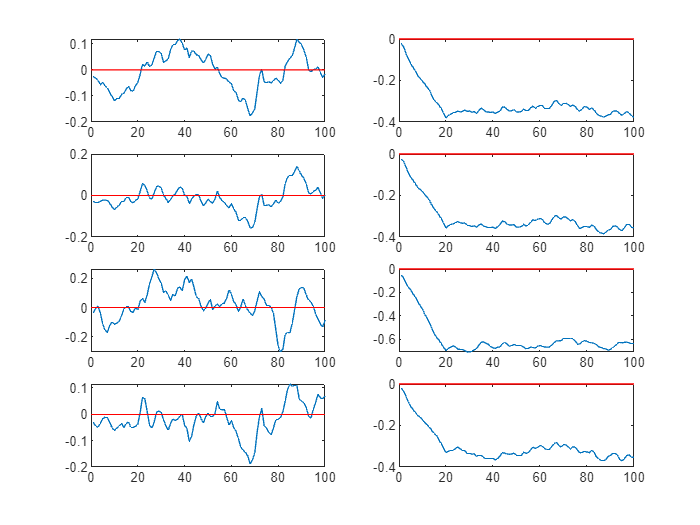


figure;
subplot(4,2,1);
plot(true_x-est_x_1);
hold on;
plot([0 100],[0 0],'r');
% plot(linspace(0,100,100),0,'r');
subplot(4,2,2);
plot(true_y-est_y_1);
hold on;
plot([0 100],[0 0],'r');

subplot(4,2,3);
plot(true_x-est_x_2);
hold on;
plot([0 100],[0 0],'r');
subplot(4,2,4);
plot(true_y-est_y_2);
hold on;
plot([0 100],[0 0],'r');

subplot(4,2,5);
plot(true_x-est_x_3);
hold on;
plot([0 100],[0 0],'r');
subplot(4,2,6);
plot(true_y-est_y_3);
hold on;
plot([0 100],[0 0],'r');

subplot(4,2,7);
plot(true_x-est_x_4);
hold on;
plot([0 100],[0 0],'r');
subplot(4,2,8);
plot(true_y-est_y_4);
hold on;
plot([0 100],[0 0],'r');

function [x,y] = gen_true_val(x,y,r)
    th = linspace(0,2*pi,100);
    x = r * cos(th) + x;
    y = r * sin(th) + y;
end

function O = gen_sens_val(true_x,true_y,sd)
    N = length(true_x);
    noise_raw_x = randn(1,N)*sd;
    noise_raw_y = rand(1,N)*sd;
    window_size = 20;
    b = ones(window_size,1)/window_size;
    a = 1;
    noise_filtered_x = filter(b, a, noise_raw_x);
    noise_filtered_y = filter(b, a, noise_raw_y);
    sens_x = (true_x + noise_filtered_x);
    sens_y = (true_y + noise_filtered_y);
    O = [sens_x;sens_y];
end

% function O = gen_sens_val(x,y,r,mu,sd)
%     th = linspace(0,2*pi,100);
%     X = null(1,length(th)+1);
%     Y = null(1,length(th)+1);
%     for c = 1:length(th)
%         x_rand = normrnd(mu,sd);
%         y_rand = normrnd(mu,sd);
%         xx = r * cos(th(c)) + x + x_rand;
%         yy = r * sin(th(c)) + y + y_rand;
%         X(c) = xx;
%         Y(c) = yy;
%     end
%     X(end) = X(1);
%     Y(end) = Y(1);
%     O = [X;Y];
% end

function draw_trajectory(x,y,clr)
    plot(x,y,clr);
end